zaimportowanie macierzy

clear;
clc;
typ = 3; %a-1,b-2,c-3
blad_res_a = zeros(17,2);
blad_res_b = zeros(17,2);
blad_res_c = zeros(17,2);

for r = 5:10:165
    for typ = 1:3
        if(typ == 1)
            temp = macierzA(r);
        elseif(typ == 2)
            temp = macierzB(r);
        elseif(typ == 3)
            temp = macierzC(r);
        end
        A = temp(:, 1:end-1);
        b = temp(:,end);
        % wywolanie funkcji Gaussa oraz residuum
        temp = gauss(A, b);
        A = temp(:, 1:end-2);
        rozwiazanie = temp(:, end-1);
        b = temp(:, end);
        a = norma_residuum(A, rozwiazanie, b);
        
        if(typ == 1)
            blad_res_a((r+5)/10,:) = [a*100000000000, r];
        elseif(typ == 2)
            blad_res_b((r+5)/10,:) = [a*100000000000, r];
        elseif(typ == 3)
            blad_res_c((r+5)/10,:) = [a, r];
        end
    end
end

utworzenie wykresow

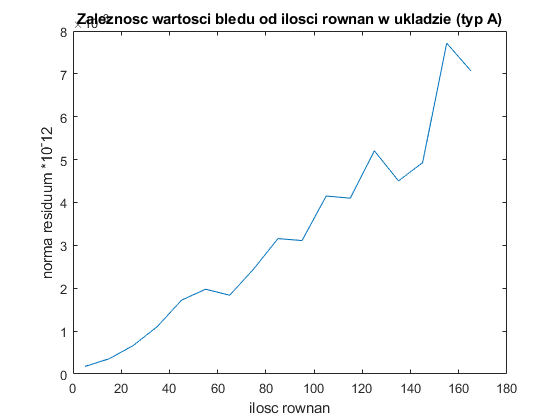

plot(blad_res_a(:,2),blad_res_a(:,1));
title('Zaleznosc wartosci bledu od ilosci rownan w ukladzie (typ A)')
xlabel('ilosc rownan') 
ylabel('norma residuum *10^-12')

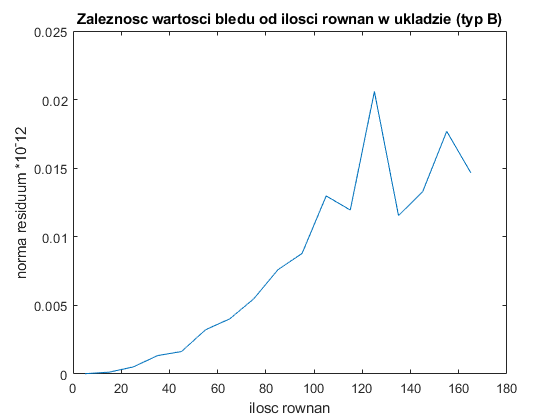


plot(blad_res_b(:,2),blad_res_b(:,1));
title('Zaleznosc wartosci bledu od ilosci rownan w ukladzie (typ B)')
xlabel('ilosc rownan') 
ylabel('norma residuum *10^-12')

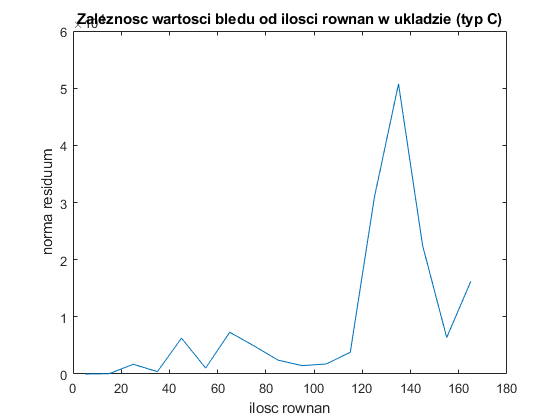


plot(blad_res_c(:,2),blad_res_c(:,1));
title('Zaleznosc wartosci bledu od ilosci rownan w ukladzie (typ C)')
xlabel('ilosc rownan') 
ylabel('norma residuum')

algorytm Gaussa

function g = gauss(wspolczynniki, rozw)
    rozmiar = size(rozw);
    pierwotne_b = rozw;
    pierwotne_wspolczynniki = wspolczynniki;
    % A B C
    % D E F
    % G H I
    % a - element uznany za glowny w danej kolumnie,
    % w tym przypadku kolejno: A, E
    % wspolczynniki(l,i) - wspolczynnik "pod schodkiem",
    % czyli tutaj: D/A, G/A, H/E
    for i = 1:(rozmiar-1)
        % wybor elementu glownego
        podmacierz = wspolczynniki(i:rozmiar, i:rozmiar);
        [el_glowny, ind_glowny] = max(podmacierz(:));
        [ind_wiersz, ind_kolumna] = ind2sub(size(podmacierz), ind_glowny);
        % z powyzszej linii uzyskujemy indexy w podmacierzy
        % wiec musimy dodac 'i-1'
        wspolczynniki([i,ind_wiersz+i-1],:) = wspolczynniki([ind_wiersz+i-1,i],:);
        pierwotne_wspolczynniki([i,ind_wiersz+i-1],:) = pierwotne_wspolczynniki([i,ind_wiersz+i-1],:);
        rozw([i,ind_wiersz+i-1],:) = rozw([ind_wiersz+i-1,i],:);
        pierwotne_b([i,ind_kolumna+i-1], :) = pierwotne_b([i,ind_kolumna+i-1], :);
        wspolczynniki(:,[i,ind_kolumna+i-1]) = wspolczynniki(:,[ind_kolumna+i-1,i]);
        pierwotne_wspolczynniki(:,[i,ind_kolumna+i-1]) = pierwotne_wspolczynniki(:,[ind_kolumna+i-1,i]);
        % wyznaczenie rozkladu LU
        a = wspolczynniki(i,i);
        for l = (i+1):rozmiar
            wspolczynniki(l,i) = wspolczynniki(l,i) / a;
            wspolczynniki(l, (i+1):end) = wspolczynniki(l, (i+1):end) - wspolczynniki(l,i) * wspolczynniki(i, (i+1):end);
            rozw(l) = rozw(l) - wspolczynniki(l,i) * rozw(i);
        end
    end
    
    % U * x = rozw -> wyznaczenie x
    for i = (rozmiar:-1:1)
        % Ax=b; -> odejmowanie wartosci znanych ze strony rozwiazan
        for j = (i+1):(rozmiar)
            rozw(i) = rozw(i) - wspolczynniki((i),(j))*wspolczynniki((j),(j));
        end
        wspolczynniki(i,i) = rozw(i)/wspolczynniki(i,i);
    end
    
    %przepisanie rozwiazan do macierzy rozw
    for i = (1:rozmiar)
        rozw(i) = wspolczynniki(i,i);
    end
    g = [pierwotne_wspolczynniki, rozw, pierwotne_b];
end

norma residuum

function nr = norma_residuum(wspolczynniki, x, rozw)
    residuum = wspolczynniki*x - rozw;
    nr = norm(residuum);
end

tworzenie macierzy typu a o zadanym rozmiarze rozmiar_a

function mac_a = macierzA(rozmiar_a)
    macierz_a = zeros(rozmiar_a);
    
    for j = 1:rozmiar_a
        for i = 1:rozmiar_a
            if (i < j-1) || (i > j+1)
                macierz_a(i,j) = 0;
            elseif (i == j-1) || (i == j+1)
                macierz_a(i,j) = 2;
            else
                macierz_a(i,j) = 6;
            end
        end
    end
    
    wolne_a = zeros(rozmiar_a, 1);
    % deklaracja pierwszej warości, aby pozostale
    % mogly powstac przez dodawanie zamiast mnozenia
    wolne_a(1) = 9.5;
    
    for i = 2:rozmiar_a
        wolne_a(i) = wolne_a(i-1) + 0.5;
    end
    
    mac_a = [macierz_a, wolne_a];
end

tworzenie macierzy typu b o zadanym rozmiarze rozmiar_b

function mac_b = macierzB(rozmiar_b)
    macierz_b = zeros(rozmiar_b);
    % wygenerowanie pierwszej i ostatniej kolumny pozwoli w pozniejszych
    % etapach przekopiowywac wartosci zamiast obliczac je na nowo
    macierz_b(1,1) = 1/8;
    macierz_b(end,end) = 1/8;
    % pierwsza kolumna
    macierz_b(2, 1) = 6;
    for i = 3:rozmiar_b
        macierz_b(i, 1) = macierz_b(i-1, 1) + 5;
    end
    % ostatnia kolumna
    macierz_b(end - 1, end) = -4;
    for i = (rozmiar_b-2):-1:1
        macierz_b(i, end) = macierz_b(i + 1, end) - 5;
    end
    
    % wykorzystanie wartosci ze skrajnych kolumn
    for j = 2:(rozmiar_b-1)
        for i = 1:rozmiar_b
            if (i < j)
                macierz_b(i,j) = macierz_b(end-(j-i),end);
            else
                macierz_b(i,j) = macierz_b(i-1,j-1);
            end
        end
    end
    
    wolne_b = zeros(rozmiar_b, 1);
    % deklaracja pierwszej warości, aby pozostale
    % mogly powstac przez dodawanie zamiast mnozenia
    wolne_b(1) = -2.5;
    
    for i = 2:rozmiar_b
        wolne_b(i) = wolne_b(i-1) + 0.5;
    end
    
    mac_b = [macierz_b, wolne_b];
end

tworzenie macierzy typu c o zadanym rozmiarze rozmiar_c

function mac_c = macierzC(rozmiar_c)
    macierz_c = zeros(rozmiar_c);
    
    % wygenerowanie pierwszej kolumny
    % kolumny od 2 do end będą przekopiowywac
    % (rozmiar_c-1) wartosci z poprzednich kolumn
    % i wyliczac jedna wlasna
    for i = 1:rozmiar_c
        macierz_c(i, 1) = 4/(5*i);
    end
    
    % wykorzystanie wartosci z pierwszej kolumny
    for j = 2:rozmiar_c
        for i = 1:(rozmiar_c-1)
            macierz_c(i,j) = macierz_c(i+1, j-1);
        end
        macierz_c(rozmiar_c, j) = 4/(5*(rozmiar_c+j-1));
    end
    wolne_c = zeros(rozmiar_c, 1);
    
    % deklaracja pierwszej warości, aby pozostale
    % mogly powstac przez dodawanie zamiast mnozenia
    wolne_c(1) = 0.5;
    
    for i = 3:2:rozmiar_c
        wolne_c(i) = wolne_c(i-2) + 1;
    end

    mac_c = [macierz_c, wolne_c];
end